# Ingeniería de Control Moderno 

### Tarea  No. 2

### Cano García Eduardo

#### 6° 6

- Un regulador tiene la planta $\frac{Y\left(s\right)}{U\left(s\right)}=\frac{10}{\left(s+1\right)\left(s+2\right)\left(s+3\right)}$. Usando las variables de estado $x_1 =y\;,x_2 =\overset{\cdot }{x_1 } \;,x_3 ={\overset{\cdot }{x} }_2$ y la ley de control $u\left(t\right)=-\textrm{Kx}$. Se desea ubicar los polos en lazo cerrado del sistema en: $s=-2\pm \textrm{j2}\sqrt{3}\;,\;s=-10$

a) Obtener analíticamente la representación en Espacio de Estados

num = 10;
den1 = conv([1 1] , [1 2]);
den2 = conv(den1 , [1 3]);
%tf = tf(num , den2)
[A,B,C,D] = tf2ss(num , den2); % Espacio de Estados
% Create a state-space system object
sys = ss(A, B, C, D);
% Display the state-space matrices
disp('State-space matrices:');

State-space matrices:


disp('A = '), disp(A);

A = 
    -6   -11    -6
     1     0     0
     0     1     0



disp('B = '), disp(B);

B = 
     1
     0
     0



disp('C = '), disp(C);

C = 
     0     0    10



disp('D = '), disp(D);

D = 
     0



b) Determinar si el sistema en espacio de estados es completamente controlable para  los estados (prueba de controlabilidad) analíticamente y/o con MATLAB.

% Aplicar la prueba de controlabilidad
controllabilityMatrix = ctrb(A, B);
disp('Matriz de Controlabilidad: '), disp(controllabilityMatrix);

Matriz de Controlabilidad: 
     1    -6    25
     0     1    -6
     0     0     1



determMatrixControl = det(controllabilityMatrix)

determMatrixControl = 1

% Rango de la matriz de Contrabilidad
rankControl = rank(controllabilityMatrix)

rankControl = 3

El orden del sistema es el mismo que la matriz de controlabilidad y su determinante es 1 lo que significa que el sistema es completamente controlable.

c) Determinar la matriz de ganancias de retroalimentación de los estados **K**,  analíticamente y/o con MATLAB. 

poles =[(-2+2*sqrt(3)*sqrt(-1)) , (-2-2*sqrt(3)*sqrt(-1)) , -10];
% Posicionarlos con la función Arker 
kA=acker(A,B,poles)

kA =     8.0000   45.0000  154.0000


%Vamos a comprobar que de lo mismo usando la función Place 
kP=place(A,B,poles)

kP =     8.0000   45.0000  154.0000


d) Simular la respuesta del sistema en lazo cerrado. Proponer condiciones iniciales.

AA = A-B*kA;
BB = eye(3);
CC = eye(3);
DD = eye(3);
syscl = ss(AA,BB,CC,DD);
% Display the state-space matrices close loop
disp('State-space matrices:');

State-space matrices:


disp('AA = '), disp(AA);

AA = 
  -14.0000  -56.0000 -160.0000
    1.0000         0         0
         0    1.0000         0



disp('BB = '), disp(BB);

BB = 
     1     0     0
     0     1     0
     0     0     1



disp('CC = '), disp(CC);

CC = 
     1     0     0
     0     1     0
     0     0     1



disp('DD = '), disp(DD);

DD = 
     1     0     0
     0     1     0
     0     0     1



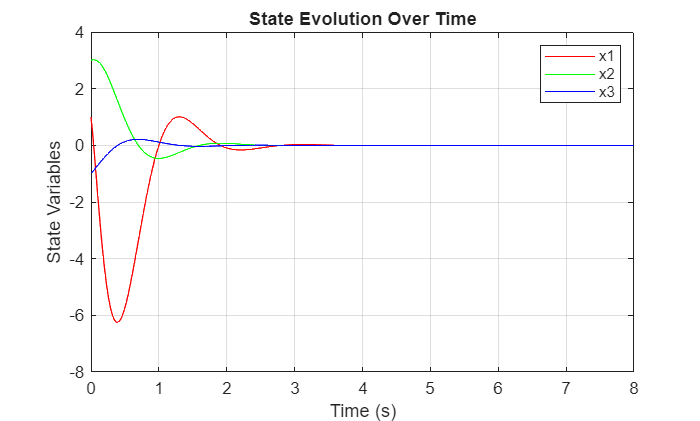

% Tiempo de simulación 
t = 0:0.01:8;
% Condiciones iniciales
x0 = [1;3;-1]; 
x = initial(syscl,x0,t);
x1 = [1 0 0 ]*x';
x2 = [0 1 0 ]*x';
x3 = [0 0 1 ]*x';
% Plot the state evolution for each state variable
figure;
plot(t, x1, 'r', t, x2, 'g', t, x3, 'b');
xlabel('Time (s)');
ylabel('State Variables');
title('State Evolution Over Time');
legend('x1', 'x2', 'x3');
grid on;

         2. Considrando el sistema del problema (1)

a) Obtener la representación en espacio de estado con la función tf2ss de  MATLAB 

num_2 = 10;
den1_2 = conv([1 1] , [1 2]);
den2_2 = conv(den1_2 , [1 3]);
tf2 = tf(num_2 , den2_2);
[A_2 , B_2 , C_2 , D_2] = tf2ss(num_2 , den2_2); % Espacio de Estados
% Create a state-space system object
sys_2 = ss(A_2 , B_2 , C_2 , D_2);
% Display the state-space matrices
disp('State-space matrices:');

State-space matrices:


disp('A = '), disp(A_2);

A = 
    -6   -11    -6
     1     0     0
     0     1     0



disp('B = '), disp(B_2);

B = 
     1
     0
     0



disp('C = '), disp(C_2);

C = 
     0     0    10



disp('D = '), disp(D_2);

D = 
     0



b) Determinar si el sistema es completamente controlable para los estados,  analíticamente y/o con MATLAB. 

% Aplicar la prueba de controlabilidad
controllabilityMatrix_2 = ctrb(A_2 , B_2);
disp('Matriz de Controlabilidad: '), disp(controllabilityMatrix_2);

Matriz de Controlabilidad: 
     1    -6    25
     0     1    -6
     0     0     1



determMatrixControl_2 = det(controllabilityMatrix_2)

determMatrixControl_2 = 1

% Rango de la matriz de Contrabilidad
rankControl_2 = rank(controllabilityMatrix_2)

rankControl_2 = 3

El orden del sistema es el mismo que la matriz de controlabilidad y su determinante es 1 lo que significa que el sistema es completamente controlable.

c) Determinar la matriz de ganancias de retroalimentación de los estados **K**,  analíticamente y/o con MATLAB. 

poles_2 =[(-2+2*sqrt(3)*sqrt(-1)) , (-2-2*sqrt(3)*sqrt(-1)) , -10];
% Posicionarlos con la función Arker 
kA_2 =acker(A,B,poles_2)

kA_2 =     8.0000   45.0000  154.0000


% Comprobamos usando la función Place 
kP_2 = place(A,B,poles_2)

kP_2 =     8.0000   45.0000  154.0000


d) Simular la respuesta del sistema en lazo cerrado. Proponer condiciones iniciales.

AA_2 = A_2-B_2*kA_2;
BB_2 = eye(3);
CC_2 = eye(3);
DD_2 = eye(3);
syscl_2 = ss(AA_2,BB_2,CC_2,DD_2);
% Display the state-space matrices close loop
disp('State-space matrices:');

State-space matrices:


disp('AA = '), disp(AA_2);

AA = 
  -14.0000  -56.0000 -160.0000
    1.0000         0         0
         0    1.0000         0



disp('BB = '), disp(BB_2);

BB = 
     1     0     0
     0     1     0
     0     0     1



disp('CC = '), disp(CC_2);

CC = 
     1     0     0
     0     1     0
     0     0     1



disp('DD = '), disp(DD_2);

DD = 
     1     0     0
     0     1     0
     0     0     1



% Tiempo de simulación 
t = 0:0.01:8;
% Condiciones iniciales
x0=[1;3;-1]; 
x = initial(syscl_2,x0,t);
x1 = [1 0 0 ]*x';
x2 = [0 1 0 ]*x';
x3 = [0 0 1 ]*x';
% Plot the state evolution for each state variable
figure;
plot(t, x1, 'r', t, x2, 'g', t, x3, 'b');
xlabel('Time (s)');
ylabel('State Variables');
title('State Evolution Over Time');
legend('x1', 'x2', 'x3');
grid on;

3. Mostrar que el sistema siguente 


$$\left\lbrack \begin{array}{c}
{\overset{\cdot }{x} }_1 \\
\overset{\cdot }{x_2 } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & 1\\
0 & 2
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack u$$


No se puede estabilizar por el control $u\left(t\right)=-\textrm{Ks}$, sin importar que matriz se elija

% Matrices de espacio de Estados 
A_3 = [0 , 1 ; 0 , 2];
B_3 = [1 ; 0];
C_3 = eye(2);
D_3 = 0;
sys_3 = ss(A_3 , B_3 , C_3 , D_3);
% Aplicar la prueba de controlabilidad para el sistema 3
controllabilityMatrix_3 = ctrb(A_3, B_3);
disp('Matriz de Controlabilidad para el sistema 3: '), disp(controllabilityMatrix_3);

Matriz de Controlabilidad para el sistema 3: 
     1     0
     0     0



determMatrixControl_3 = det(controllabilityMatrix_3)

determMatrixControl_3 = 0

% Rango de la matriz de Contrabilidad para el sistema 3
rankControl_3 = rank(controllabilityMatrix_3)

rankControl_3 = 1

El orden del sistema no es el mismo que la matriz de controlabilidad y su determinante es 0 lo que significa que el sistema es no controlable.

4. Para el sistema definido por la ecuación siguente:

$\overset{\cdot }{x} =\textrm{Ax}+\textrm{Bu}$, $y=\textrm{Cx}$, donde


$$A=\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
-1 & -5 & -6
\end{array}\right\rbrack ,B=\left\lbrack \begin{array}{c}
0\\
1\\
1
\end{array}\right\rbrack$$


Usando el control con retroalimentación de los estados $u\left(t\right)=-\textrm{Kx}$, se desea tener los polos en lazo cerrado en $s=-2\pm \textrm{j4},s=-10$

A_4 = [0 1 0 ; 0 0 1 ; -1 -5 -6];
B_4 = [0 ; 1 ; 1];

a) Verificar si el sistema es completamente controlable para los estados, analíticamente y/o mediante MATLAB. 

% Aplicar la prueba de controlabilidad para el sistema 3
controllabilityMatrix_4 = ctrb(A_4, B_4);
disp('Matriz de Controlabilidad para el sistema 4: '), disp(controllabilityMatrix_4);

Matriz de Controlabilidad para el sistema 4: 
     0     1     1
     1     1   -11
     1   -11    60



determMatrixControl_4 = det(controllabilityMatrix_4)

determMatrixControl_4 = -83

% Rango de la matriz de Contrabilidad para el sistema 3
rankControl_4 = rank(controllabilityMatrix_4)

rankControl_4 = 3

El orden del sistema es el mismo que la matriz de controlabilidad y su determinante es -83 lo que significa que el sistema es controlable.

b) Determinar la matriz de ganancias para los estados (K) analíticamente y/o  mediante MATLAB. 

poles_4 =[(-2+2*j*4) , (-2-2*j*4) , -10];
% Posicionarlos con la función Arker 
kA_4 =acker(A_4,B_4,poles_4)

kA_4 =    97.6024    3.7831    4.2169


% Comprobamos usando la función Place 
kP_4 = place(A_4,B_4,poles_4)

kP_4 =    97.6024    3.7831    4.2169


c) Simular la respuesta del sistema en lazo cerrado. Proponer condiciones iniciales 

AA_4 = A_4-B_4*kA_4;
BB_4 = eye(3);
CC_4 = eye(3);
DD_4 = eye(3);
syscl_4 = ss(AA_4,BB_4,CC_4,DD_4);
% Display the state-space matrices close loop
disp('State-space matrices:');

State-space matrices:


disp('AA = '), disp(AA_4);

AA = 
         0    1.0000         0
  -97.6024   -3.7831   -3.2169
  -98.6024   -8.7831  -10.2169



disp('BB = '), disp(BB_4);

BB = 
     1     0     0
     0     1     0
     0     0     1



disp('CC = '), disp(CC_4);

CC = 
     1     0     0
     0     1     0
     0     0     1



disp('DD = '), disp(DD_4);

DD = 
     1     0     0
     0     1     0
     0     0     1



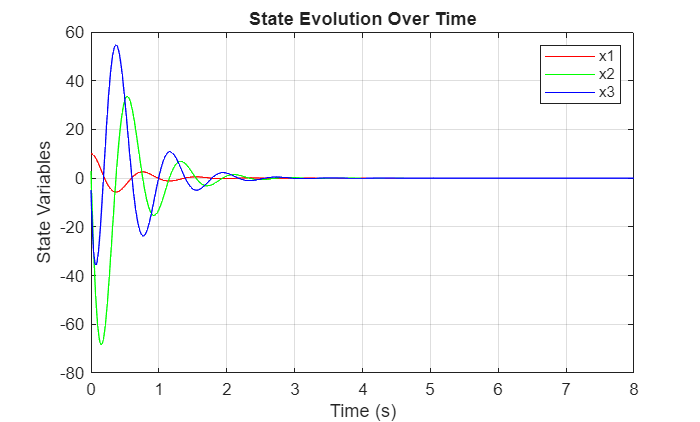

% Tiempo de simulación 
t_4 = 0:0.01:8;
% Condiciones iniciales
x0_4=[10;3;-5]; 
x = initial(syscl_4,x0_4,t_4);
x1 = [1 0 0 ]*x';
x2 = [0 1 0 ]*x';
x3 = [0 0 1 ]*x';
% Plot the state evolution for each state variable
figure;
plot(t_4, x1, 'r', t_4, x2, 'g', t_4, x3, 'b');
xlabel('Time (s)');
ylabel('State Variables');
title('State Evolution Over Time');
legend('x1', 'x2', 'x3');
grid on;

5. Para el sistema definido por la ecuación siguente:

$\overset{\cdot }{x} =\textrm{Ax}+\textrm{Bu}$, $y=\textrm{Cx}$, donde


$$A=\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
0 & -5 & -6
\end{array}\right\rbrack ,B=\left\lbrack \begin{array}{c}
0\\
1\\
1
\end{array}\right\rbrack ,C=\left\lbrack \begin{array}{ccc}
1 & 0 & 0
\end{array}\right\rbrack$$


con la ley de control $u\left(t\right)=k_1 r-\left(k_1 x_1 +k_2 x_2 +k_3 x_3 \right)$.

A_5 = [0 1 0 ; 0 0 1 ; 0 -5 -6];
B_5 = [0 ; 0 ; 1];
C_5 = [1 0 0];
D_5 = 0;

a) Verificar si el sistema es controlable para los estados. 

% Aplicar la prueba de controlabilidad para el sistema 3
controllabilityMatrix_5 = ctrb(A_5, B_5);
disp('Matriz de Controlabilidad para el sistema 5: '), disp(controllabilityMatrix_5);

Matriz de Controlabilidad para el sistema 5: 
     0     0     1
     0     1    -6
     1    -6    31



determMatrixControl_5 = det(controllabilityMatrix_5)

determMatrixControl_5 = -1

% Rango de la matriz de Contrabilidad para el sistema 3
rankControl_5 = rank(controllabilityMatrix_5)

rankControl_5 = 3

El orden del sistema es el mismo que la matriz de controlabilidad y su determinante es -1 lo que significa que el sistema es controlable.

b) Determinar las constantes ganancias de retroalimentación de los estados $k_1 {\;,\;k}_2 \;,{\;k}_3$ tal que los polos deseados en lazo cerrado estén localizados en $s_1 =-2+\textrm{j4}\;,s_2 =-2-4j\;,s=-10$

poles_5 =[(-2+j*4) , (-2-j*4) , -10];
% Posicionarlos con la función Arker 
kA_5 =acker(A_5,B_5,poles_5)
% Comprobamos usando la función Place 
kP_5 = place(A_5,B_5,poles_5)
k1_5 = kA_5(1)

kA_5 =    200    55     8


kP_5 =   200.0000   55.0000    8.0000


k1_5 = 200

k2_5 = kA_5(2)

k2_5 = 55

k3_5 = kA_5(3)

k3_5 = 8

c) Obtener la respuesta del sistema a una entrada escalón unitaria.

AA_5 = A_5-B_5*kA_5;
BB_5 = B_5*k1_5;
CC_5 = C_5;
DD_5 = D_5;
syscl_5 = ss(AA_5,BB_5,CC_5,DD_5);
% Display the state-space matrices close loop
disp('State-space matrices:');

State-space matrices:


disp('AA = '), disp(AA_5);

AA = 
     0     1     0
     0     0     1
  -200   -60   -14



disp('BB = '), disp(BB_5);

BB = 
     0
     0
   200



disp('CC = '), disp(CC_5);

CC = 
     1     0     0



disp('DD = '), disp(DD_5);

DD = 
     0



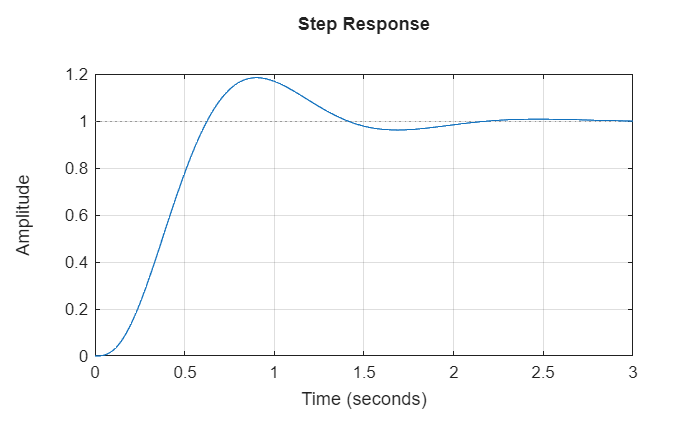

step(syscl_5)
grid on

6. Un péndulo invertido es descrito mediante las ecuaciones diferenciales siguientes: $\overset{\cdot \cdot }{\theta} =\frac{M+m}{M\cdot l}g\theta -u;\;\overset{\cdot \cdot }{x} =\frac{u}{M}-\frac{\textrm{mg}}{M}\theta ,\;\textrm{donde}\;\theta \;\textrm{es}\;\textrm{la}\;\textrm{rotación}\;\textrm{de}\;\textrm{la}\;\textrm{barra}\;\textrm{del}\;\textrm{péndulo}\;y\;x\;\textrm{es}\;\textrm{la}\;\textrm{posición}\;\textrm{del}\;\textrm{carro}\ldotp$ Si M=2 Kg, m=0.5 kg y l= 1  m. Utilizando las variables de  estado $x_1 =\theta \;,x_2 =\overset{\cdot }{\theta} \;,x_3 =x\;,x_4 =\overset{\cdot }{x}$ y las variables de salida $y_1 =\theta =x_1 \;,y_2 =x=x_3$.

Escriba las ecuaciones de estado $\overset{\cdot }{x} =\textrm{Ax}+\textrm{Bu};y=\textrm{Cx}$

A_6 = [0 1 0 0 ; 12.26 0 0 0 ; 0 0 0 1 ; -2.45 0 0 0];
B_6 = [0 ; -1 ; 0 ; 0.5];
C_6 = [1 0 0 0 ; 0 0 1 0];
D_6 = 0;

b. Verificar si el sistema es completamente controlable para los estados.

% Aplicar la prueba de controlabilidad para el sistema 6
controllabilityMatrix_6 = ctrb(A_6, B_6);
disp('Matriz de Controlabilidad para el sistema 6: '), disp(controllabilityMatrix_6);

Matriz de Controlabilidad para el sistema 6: 
         0   -1.0000         0  -12.2600
   -1.0000         0  -12.2600         0
         0    0.5000         0    2.4500
    0.5000         0    2.4500         0



determMatrixControl_6 = det(controllabilityMatrix_6)

determMatrixControl_6 = 13.5424

% Rango de la matriz de Contrabilidad para el sistema 3
rankControl_6 = rank(controllabilityMatrix_6)

rankControl_6 = 4

El orden del sistema es el mismo que la matriz de controlabilidad y su determinante es 13.5424 lo que significa que el sistema es controlable.

b. Determine la matriz K de retroalimentación para los estados, usando los polos  deseados en lazo cerrado $s_1 =-4+\textrm{j4}\;,s_2 =-4-\textrm{j4}\;,s_3 =-20\;,s_4 =-20$

poles_6 =[(-4+j*4) , (-4-j*4) , -20 , -20];
% Posicionarlos con la función Arker 
kA_6 =acker(A_6,B_6,poles_6)

kA_6 = 1.0e+03 *

   -2.5034   -0.6567   -3.4783   -1.2174


% Comprobamos usando la función Place 
%kP_6 = place(A_6,B_6,poles_6)

c) Escriba un programa en MATLAB para obtener la respuesta del sistema de control  a una condición inicial arbitraria. Utilice como condiciones iniciales $x_1 \left(0\right)=0\;,x_2 \left(0\right)=0\;,x_3 \left(0\right)=0\;,x_4 \left(0\right)=1\;\frac{m}{s}$

AA_6 = A_6-B_6*kA_6;
BB_6 = eye(4);
CC_6 = eye(4);
DD_6 = eye(4);
syscl_6 = ss(AA_6,BB_6,CC_6,DD_6);
% Display the state-space matrices close loop
disp('State-space matrices:');

State-space matrices:


disp('AA = '), disp(AA_6);

AA = 
   1.0e+03 *

         0    0.0010         0         0
   -2.4911   -0.6567   -3.4783   -1.2174
         0         0         0    0.0010
    1.2492    0.3283    1.7391    0.6087



disp('BB = '), disp(BB_6);

BB = 
     1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1



disp('CC = '), disp(CC_6);

CC = 
     1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1



disp('DD = '), disp(DD_6);

DD = 
     1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1



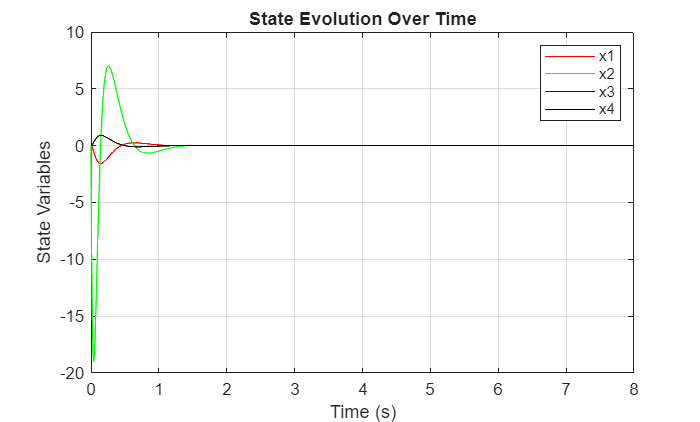

% Tiempo de simulación 
t = 0:0.01:8;
% Condiciones iniciales
x0=[0;0;0;1]; 
x = initial(syscl_6,x0,t);
x1 = [1 0 0 0]*x';
x2 = [0 1 0 0]*x';
x3 = [0 0 1 0]*x';
x4 = [0 0 1 0]*x';
% Plot the state evolution for each state variable
figure;
plot(t, x1, 'r', t, x2, 'g', t, x3, 'b', t, x4, 'k');
xlabel('Time (s)');
ylabel('State Variables');
title('State Evolution Over Time');
legend('x1', 'x2', 'x3', 'x4');
grid on;

d) Escriba un programa en MATLAB para obtener la respuesta del sistema de control  a una entrada escalón unitaria.

AA_6_2 = A_6-B_6*kA_6;
BB_6_2 = B_6*kA_6(1);
CC_6_2 = C_6;
DD_6_2 = D_6;
syscl_6_2 = ss(AA_6_2,BB_6_2,CC_6_2,DD_6_2);
% Display the state-space matrices close loop
disp('State-space matrices:');

State-space matrices:


disp('AA = '), disp(AA_6_2);

AA = 
   1.0e+03 *

         0    0.0010         0         0
   -2.4911   -0.6567   -3.4783   -1.2174
         0         0         0    0.0010
    1.2492    0.3283    1.7391    0.6087



disp('BB = '), disp(BB_6_2);

BB = 
   1.0e+03 *

         0
    2.5034
         0
   -1.2517



disp('CC = '), disp(CC_6_2);

CC = 
     1     0     0     0
     0     0     1     0



disp('DD = '), disp(DD_6_2);

DD = 
     0



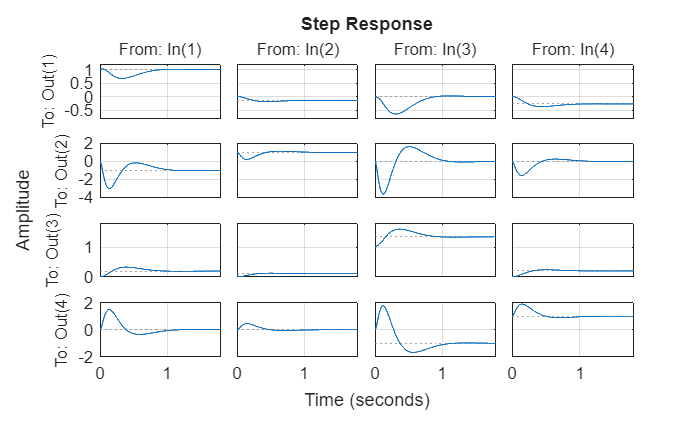

step(syscl_6)
grid on

7. Para el sistema en espacio de estados siguiente:

$\overset{\cdot }{x} =\textrm{Ax}+\textrm{Bu}$, $y=\textrm{Cx}$, donde


$$A=\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
-5 & -6 & 0
\end{array}\right\rbrack ,B=\left\lbrack \begin{array}{c}
0\\
1\\
1
\end{array}\right\rbrack ,C=\left\lbrack \begin{array}{ccc}
1 & 0 & 0
\end{array}\right\rbrack$$


.

A_7 = [0 1 0 ; 0 0 1 ; -5 -6 0];
B_7 = [0 ; 0 ; 1];
C_7 = [1 0 0];
D_7 = 0;

a) Verificar que el sistema es completamente observable (prueba de observabilidad).  

% Aplicar la prueba de observavilidad
sys_7 = ss(A_7,B_7,C_7,D_7);
observabilityMatrix_7 = obsv(A_7,C_7);
disp('Matriz de Observabilidad para el sistema 7: '), disp(observabilityMatrix_7);

Matriz de Observabilidad para el sistema 7: 
     1     0     0
     0     1     0
     0     0     1



rank(observabilityMatrix_7)

ans = 3

rank(obsv(sys_7))

ans = 3

order(sys_7)

ans = 3

El orden y rango del sistema es el mismo que la matriz de observabilidad lo que significa que el sistema es observable.

b) Diseñar un observador para los estados de orden completo, suponiendo que los  polos deseados son $s_1 =-10\;,s_2 =-10\;,s_3 =-15$

% Comprobamos la observabilidad usando la función Place
poles_7 = [-10, -10, -15];
kP_7 = acker(A_7', C_7', poles_7)'

kP_7 =           35
         394
        1285


8. Para el sistema indicado en el diagrama siguiente

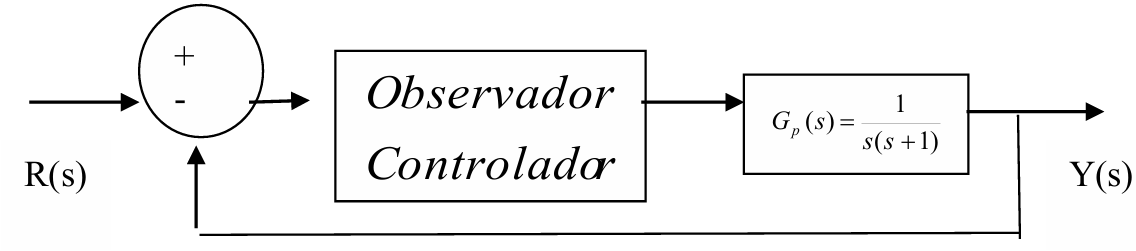

a) Obtener la representación de la planta en espacio de estados  

num = 1;
den = [1 1 0];
tfsys = tf(num,den)


tfsys =
 
     1
  -------
  s^2 + s
 
Continuous-time transfer function.


[A_8,B_8,C_8,D_8] = tf2ss(num,den)

A_8 =     -1     0
     1     0


B_8 =      1
     0


C_8 =      0     1


D_8 = 0

b) Verificar que el sistema es controlable. 

% Aplicar la prueba de controlabilidad para el sistema 8
controllabilityMatrix_8 = ctrb(A_8, B_8);
disp('Matriz de Controlabilidad para el sistema 8: '), disp(controllabilityMatrix_8);

Matriz de Controlabilidad para el sistema 8: 
     1    -1
     0     1



determMatrixControl_8 = det(controllabilityMatrix_8)

determMatrixControl_8 = 1

% Rango de la matriz de Contrabilidad para el sistema 8
rankControl_8 = rank(controllabilityMatrix_8)

rankControl_8 = 2

El orden del sistema es el mismo que la matriz de controlabilidad y su determinante es 1 lo que significa que el sistema es controlable.

c) Verificar que el sistema es observable. 

% Aplicar la prueba de observavilidad
sys_8 = ss(A_8,B_8,C_8,D_8);
observabilityMatrix_8 = obsv(A_8,C_8);
disp('Matriz de Observabilidad para el sistema 8: '), disp(observabilityMatrix_8);

Matriz de Observabilidad para el sistema 8: 
     0     1
     1     0



rank(observabilityMatrix_8)

ans = 2

rank(obsv(sys_8))

ans = 2

order(sys_8)

ans = 2

El orden y rango del sistema es el mismo que la matriz de observabilidad lo que significa que el sistema es observable.